clear; clc;
format long;
hp = csvread('multiplicationDataHP.csv', 1, 0);
apple = csvread('multiplicationDataMBPro.csv', 1, 0);

ls_hp_m = LeastSquare;
ls_hp_m.A = hp(:,1);
ls_hp_m.b = hp(:,2);
resultVector_hp_m = ls_hp_m.solveLeastSquare(3);

start least square
Elapsed time is 0.000193 seconds.
Elapsed time is 0.000500 seconds.


flipVector_hp_m = flipud(resultVector_hp_m);
polynom_hp_m = poly2sym(flipVector_hp_m);

ls_hp_t = LeastSquare;
ls_hp_t.A = hp(:,1);
ls_hp_t.b = hp(:,3);
resultVector_hp_t = ls_hp_t.solveLeastSquare(3);

start least square
Elapsed time is 0.000198 seconds.
Elapsed time is 0.000358 seconds.


flipVector_hp_t = flipud(resultVector_hp_t);
polynom_hp_t = poly2sym(flipVector_hp_t);

ls_hp_mt = LeastSquare;
ls_hp_mt.A = hp(:,2);
ls_hp_mt.b = hp(:,3);
resultVector_hp_mt = ls_hp_mt.solveLeastSquare(3);

start least square
Elapsed time is 0.000184 seconds.
Elapsed time is 0.000352 seconds.


flipVector_hp_mt = flipud(resultVector_hp_mt);
polynom_hp_mt = poly2sym(flipVector_hp_mt);

ls_a_m = LeastSquare;
ls_a_m.A = apple(:,1);
ls_a_m.b = apple(:,2);
resultVector_a_m = ls_a_m.solveLeastSquare(3);

start least square
Elapsed time is 0.000217 seconds.
Elapsed time is 0.000452 seconds.


flipVector_a_m = flipud(resultVector_a_m);
polynom_a_m = poly2sym(flipVector_a_m);

ls_a_t = LeastSquare;
ls_a_t.A = apple(:,1);
ls_a_t.b = apple(:,3);
resultVector_a_t = ls_a_t.solveLeastSquare(3);

start least square
Elapsed time is 0.000225 seconds.
Elapsed time is 0.000397 seconds.


flipVector_a_t = flipud(resultVector_a_t);
polynom_a_t = poly2sym(flipVector_a_t);

ls_a_mt = LeastSquare;
ls_a_mt.A = apple(:,2);
ls_a_mt.b = apple(:,3);
resultVector_a_mt = ls_a_mt.solveLeastSquare(3);

start least square
Elapsed time is 0.000432 seconds.
Elapsed time is 0.000600 seconds.


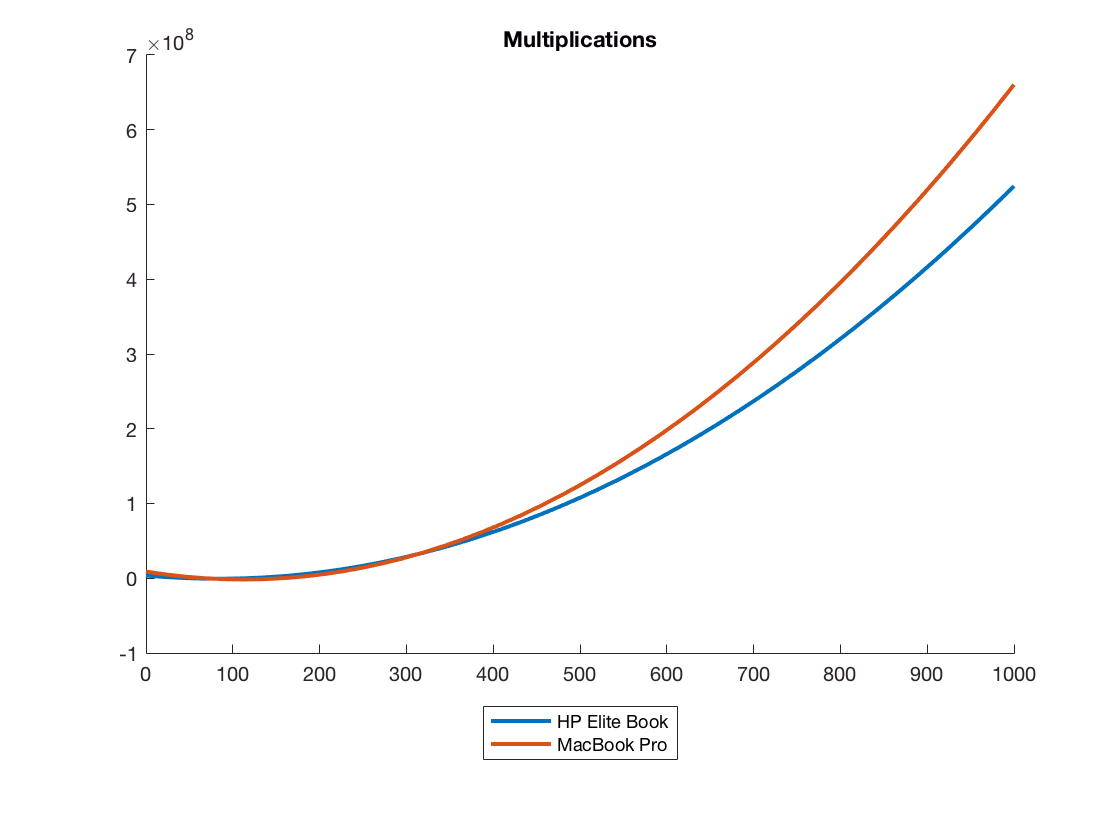

flipVector_a_mt = flipud(resultVector_a_mt);
polynom_a_mt = poly2sym(flipVector_a_mt);

figure;
hold on;
plot1 = fplot(polynom_hp_m, [0, 10E2], 'LineWidth',2);
label1 = 'HP Elite Book';
hold off;

hold on;
plot2 = fplot(polynom_a_m, [0, 10E2], 'LineWidth',2);
label2 = 'MacBook Pro';
hold off;

title('Multiplications');
legend(label1, label2, 'Location','southoutside');

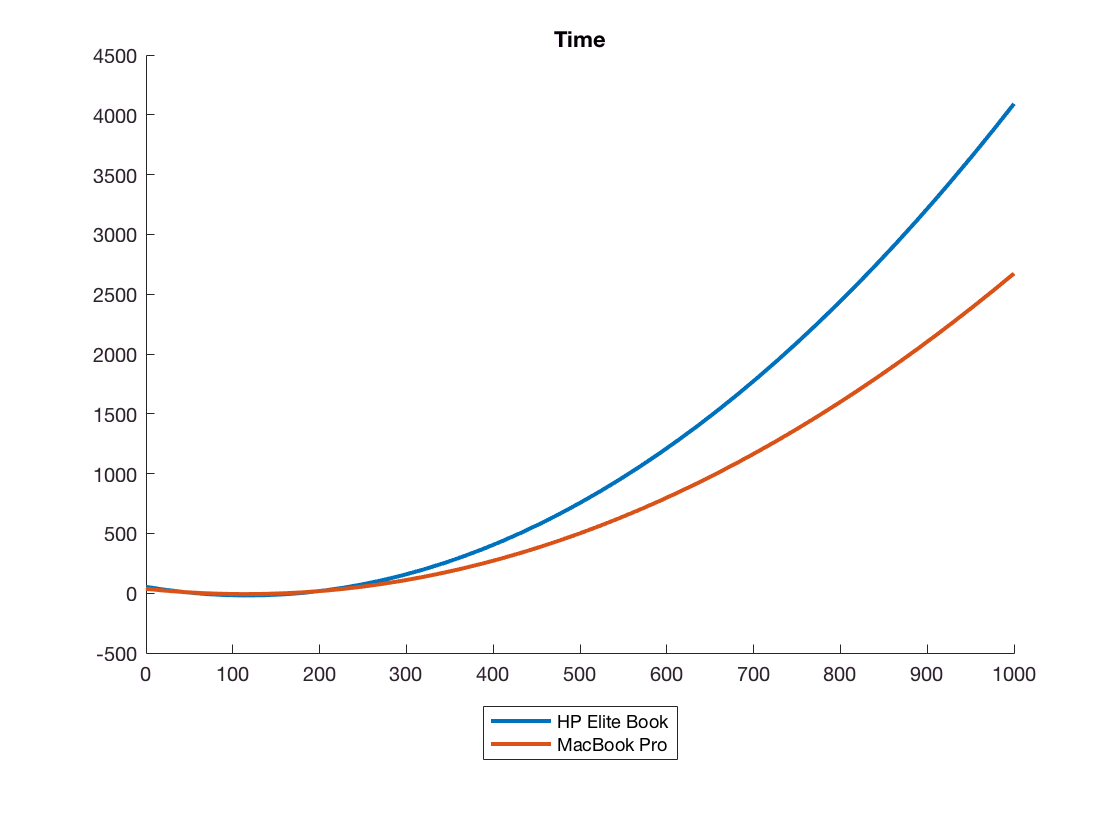


figure;
hold on;
plot3 = fplot(polynom_hp_t, [0, 10E2],  'LineWidth',2);
label3 = 'HP Elite Book';
hold off;

hold on;
plot4 = fplot(polynom_a_t, [0, 10E2], 'LineWidth',2);
label4 = 'MacBook Pro';
hold off;

title('Time');
legend(label3, label4,'Location','southoutside');

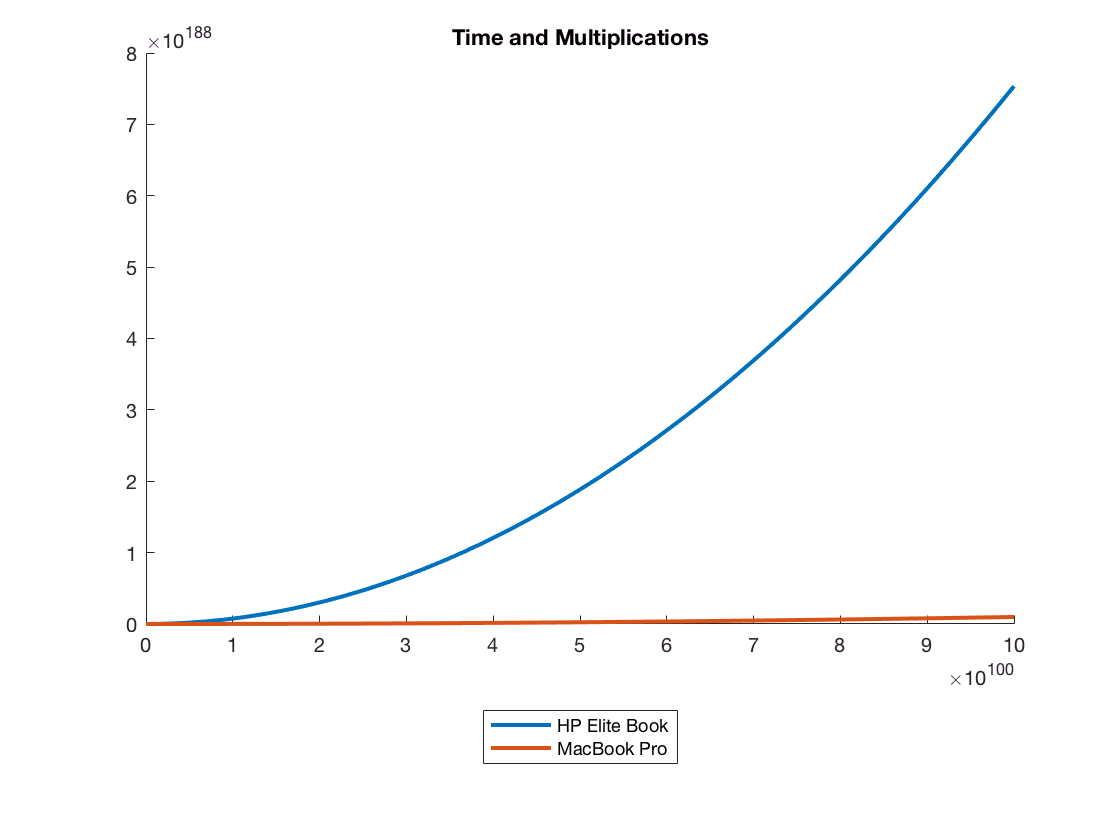


figure;
hold on;
plot5 = fplot(polynom_hp_mt, [0, 10E5],  'LineWidth',2);
label5 = 'HP Elite Book';
hold off;

hold on;
plot6 = fplot(polynom_a_mt, [0, 10E5], 'LineWidth',2);
label6 = 'MacBook Pro';
hold off;

title('Time and Multiplications');
legend(label5, label6, 'Location','southoutside');